#     Plan Mobile Robot Paths Using RRT

This example shows how to use the rapidly exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application. 

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

load("office_area_gridmap.mat","occGrid")
show(occGrid)

% Set start and goal poses for agent A
Astart = [-1,0,-pi];
Agoal = [14,-2.25,0];

% Set start and goal poses for agent B
Bstart = [-5,0,0];
Bgoal = [13,3,-pi];

% MAKING THE TASKSET WITH STARTING AND GOAL POSITION



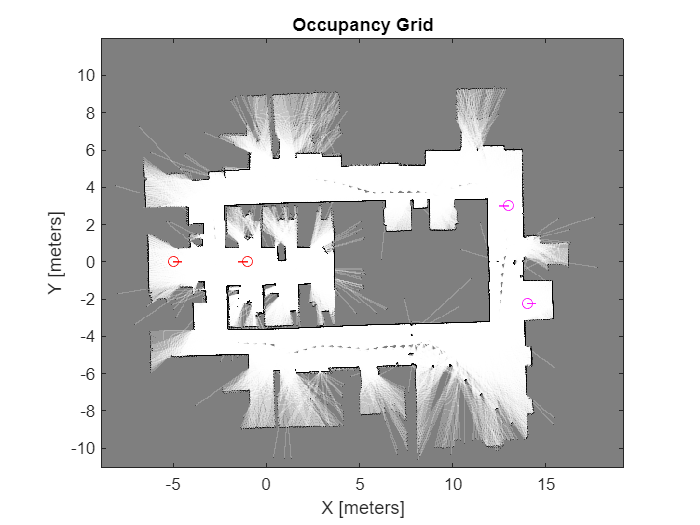

% Show start and goal positions of robot.
hold on
% for agent A
plot(Astart(1),Astart(2),'ro')
plot(Agoal(1),Agoal(2),'mo')

% for agent B
plot(Bstart(1),Bstart(2),'ro')
plot(Bgoal(1),Bgoal(2),'mo')


% Show start and goal heading for agent A
r = 0.5;
plot([Astart(1),Astart(1) + r*cos(Astart(3))],[Astart(2),Astart(2) + r*sin(Astart(3))],'r-')
plot([Agoal(1),Agoal(1) + r*cos(Agoal(3))],[Agoal(2),Agoal(2) + r*sin(Agoal(3))],'m-')

% Show start and goal heading for agent A

plot([Bstart(1),Bstart(1) + r*cos(Bstart(3))],[Bstart(2),Bstart(2) + r*sin(Bstart(3))],'r-')
plot([Bgoal(1),Bgoal(1) + r*cos(Bgoal(3))],[Bgoal(2),Bgoal(2) + r*sin(Bgoal(3))],'m-')

hold off

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4 meters allows for tight turns in this small environment.

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05 m. This validation distance discretizes the path connections and checks obstacles in the map based on this.  

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 1;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator for reproducible results. 

rng default

% planning initially for agent A
[pthObjA, solnInfoA] = plan(planner,Astart,Agoal);

% save all the nodes in a array for agent A
NodesA=pthObjA.States;

% x=NodesA(1,2);

% planning initially for agent B
[pthObjB, solnInfoB] = plan(planner,Bstart,Bgoal);

% save all the nodes in a array for agent B
NodesB=pthObjB.States;


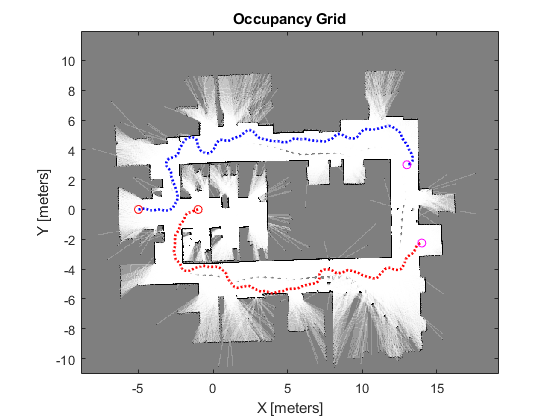

% now implementing rrt between two consecutive nodes using a loop

% Initialize arrays to store states
allStatesA = [];
allStatesB = [];


nodescount= numel(NodesA(:,1)); % finding the total number of nodes in the final path, now its same, but would take the smaller one

for n=1:nodescount-1


%%%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%
statusA=0;
statusB=1;

[finalpathA, solutionA]= interplanner(n,NodesA,NodesB,statusA,statusB);



statusA=1;
statusB=0;

[finalpathB, solutionB]= interplanner(n,NodesA,NodesB,statusA,statusB);
%%%%%%%%%%%%%%%%%%%% updating the paths %%%%%%%%%%%%%%%%%%%%



%%%%%%%%% animating the paths %%%%%%%%%

% Store the states for plotting
allStatesA = [allStatesA; finalpathA.States];
allStatesB = [allStatesB; finalpathB.States];

% Clear the current figure
clf;

% Show the occupancy grid
show(occGrid);
hold on;


% Plot all previous states of pthObjA
plot(allStatesA(:,1), allStatesA(:,2), 'r-', 'LineWidth', 2, 'LineStyle', ':');


% Interpolate and plot path for pthObjA
% interpolate(finalpathA,300);
plot(finalpathA.States(:,1),finalpathA.States(:,2),'r-','LineWidth',2);

 
% Show start and goal in grid map for pthObjA
plot(Astart(1),Astart(2),'ro');
plot(Agoal(1),Agoal(2),'mo');

% Plot all previous states of pthObjB
plot(allStatesB(:,1), allStatesB(:,2), 'b-', 'LineWidth', 2, 'LineStyle', ':');

% send this finalpath to plot the states for agent A from n=1 to n-2  

% Interpolate and plot path for pthObjB
% interpolate(finalpathB,300);
plot(finalpathB.States(:,1),finalpathB.States(:,2),'b-','LineWidth',2);


% Show start and goal in grid map for pthObjB
plot(Bstart(1),Bstart(2),'ro');
plot(Bgoal(1),Bgoal(2),'mo');


hold off 


% Pause for a short duration to allow figure to update
pause(0.1); % Adjust the duration as needed

end

*Copyright 2019 The MathWorks, Inc.*